syms y(t)
eqn = diff(y ,t) == -12 * y;
cond = y(0) == 1;
dsolve(eqn,cond);
exactSol = @(t)(exp(-12 * t));

f = @(t,y) -12 * y;
a = 0;
b = 1;
alpha = 1;
N1 = 20;
N2 = 50; 
N3 = 100;
N = [N1, N2, N3];

[y6,t6] = AB4(f, a, b, alpha,N1)

y6 =     1.0000
    0.5494
    0.3018
    0.1658
    0.0998
    0.0516
    0.0424
    0.0051
    0.0354
   -0.0334


t6 =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


[y7,t7] = AB4(f, a, b, alpha,N2)

y7 =     1.0000
    0.7866
    0.6188
    0.4868
    0.3831
    0.3014
    0.2372
    0.1867
    0.1469
    0.1156


t7 =          0
    0.0200
    0.0400
    0.0600
    0.0800
    0.1000
    0.1200
    0.1400
    0.1600
    0.1800


[y8,t8] = AB4(f, a, b, alpha,N3)

y8 =     1.0000
    0.8869
    0.7866
    0.6977
    0.6188
    0.5488
    0.4868
    0.4317
    0.3829
    0.3396


t8 =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


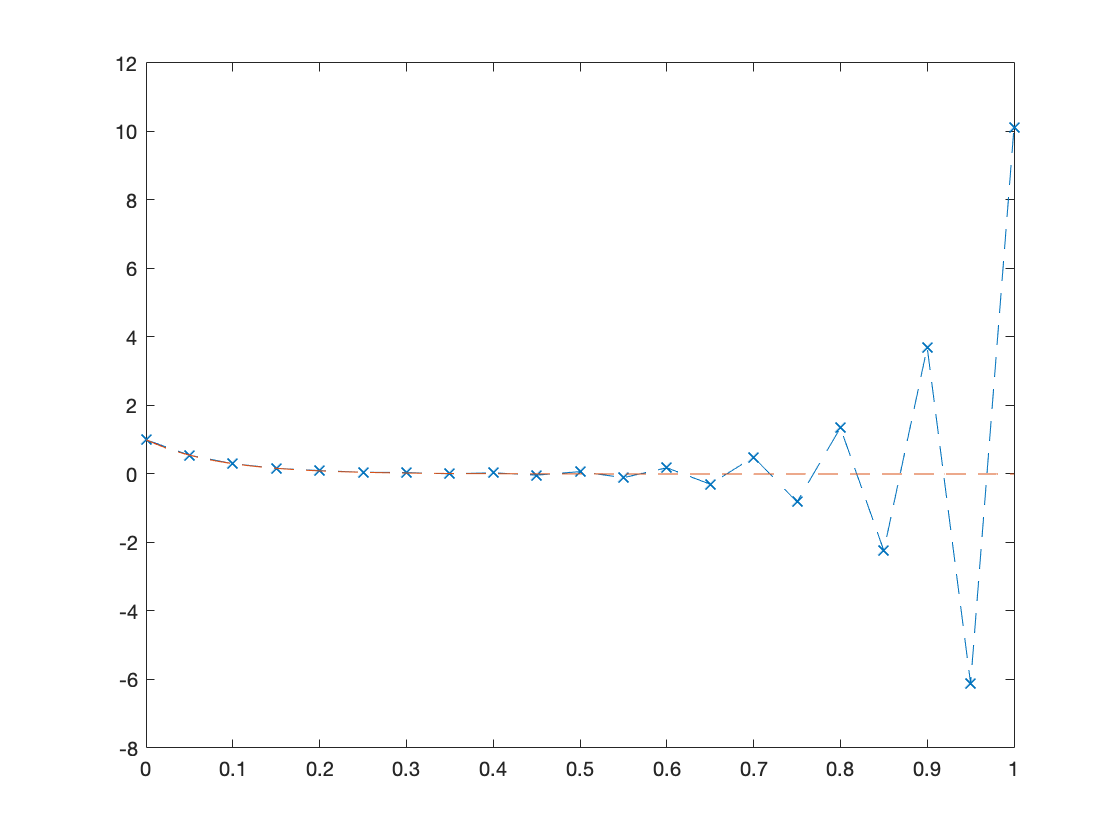


err1 = abs(y6(end) - exactSol(1));
err2 = abs(y7(end) - exactSol(1));
err3 = abs(y8(end) - exactSol(1));
Err2 = [err1, err2, err3];

% plot(t0, y0, '--x', t1, y1, '--r', t2, y2, '--')

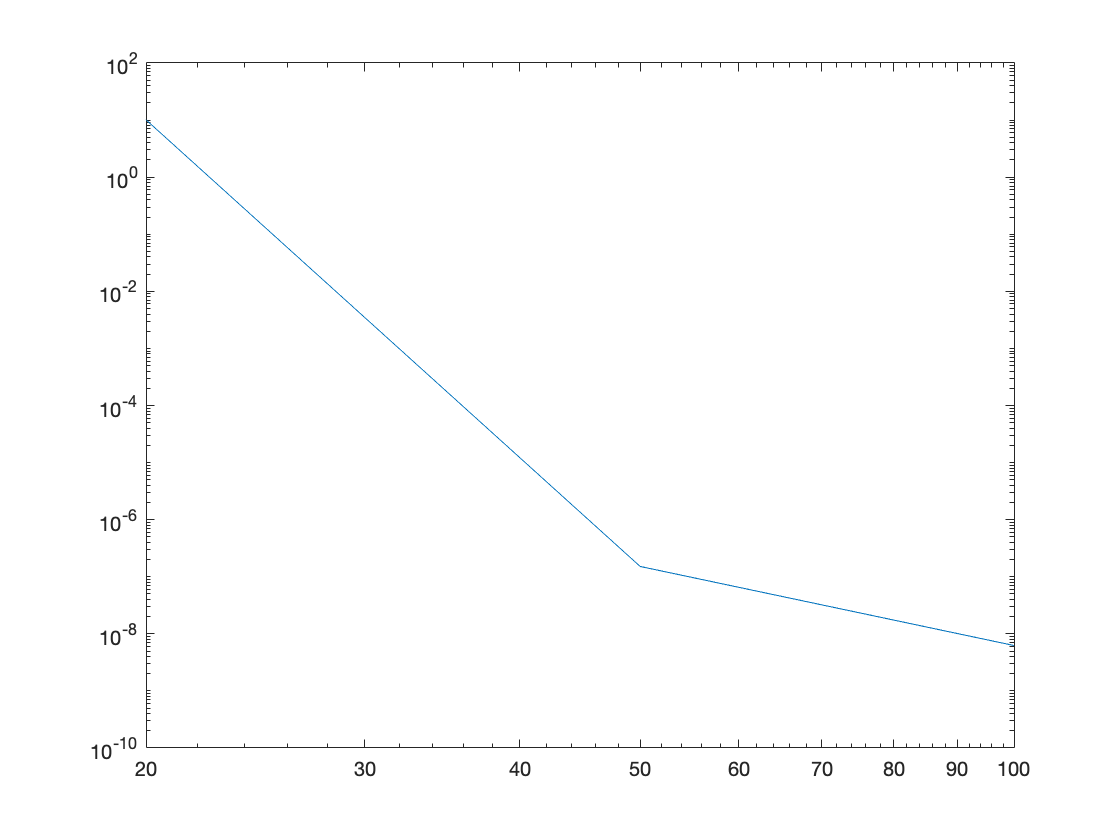

loglog(N, Err2)

function [y,t] = AB4(f,a,b,alpha,N)
   %function that computes solve the IVP using four step Adams-Bashforth method
    %INPUTS: 
    %function f
    %initial condition alpha
    %bounds of interval [a,b]
    %N number of nodes used
    %yinit: first 4 values of the soltuion
    %OUTPUT: 
    %y the solution
    %t the time sequence
    
    %creation of the nodes and time step
    t = zeros(N+1,1);
    h = (b-a)/(N);
    for i = 1:N+1
        t(i) = a + (i-1) *h;
    end
    
    %creation solution via AB4 method
    y = zeros(N+1,1);
    y(1) = alpha;
    %use RK4 for the first steps
    for i = 2:4
        k1 = h* f(t(i-1),y(i-1));
        k2 = h * f(t(i-1) + (1/2)*h, y(i-1) + (1/2)*k1);
        k3 = h * f(t(i-1) + (1/2)*h, y(i-1) + (1/2)*k2);
        k4 = h * f(t(i), y(i-1) + k3);
        y(i) = y(i-1) + (k1 + 2*k2 + 2*k3 +k4)/6;
    end
    %use AB4 for the rest
    for i = 5:N+1
        y(i) = y(i-1) + h/24 * ( 55 * f(t(i-1), y(i-1)) ...
            -59 * f(t(i-2), y(i-2)) + 37 * f(t(i-3), y(i-3)) ...
            - 9 * f(t(i-4), y(i-4)) );
    end
end